% calculate and plot state value

Animal = 'tph189';
Date = '20230418';
totalTrial = 150;
Key = 'uniform';
gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
behavior_data = behavior_neural_time_convolved_zscored;

% neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
neural_activity_table = readtable([data_folder filesep 'cell_traces.csv']);%,'NumHeaderLines',1); #Linux
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));

neural_activity_data

neural_activity_data =     5.9168   20.2242   12.2416    1.9740    6.1397   31.3767   -3.0355    0.2301   24.0171    0.9025   -0.9259    3.2175    7.9564   -2.8275   10.7867   18.7352    7.3628   10.1516    9.5282    1.9840   18.5185    3.3818   -1.5787   -1.6623    0.8142   19.8975    8.4732    8.6004   -1.2689   -0.0600    2.2676   16.1664    1.7839   10.2772   -0.1967   23.1989   -0.2973    2.7365    3.8236   44.8459    7.4560    7.2730   -2.5544   11.9062    3.3925    3.8500   13.8883   13.9680   11.1083   -2.5511
    6.0606   22.3476   12.7419    0.2299    4.2129   33.2336   -2.7216    0.6801   26.2001    2.3410   -2.0958    2.5727    8.2855   -2.7670   13.6843   17.3248    8.3716    7.4441    9.6469    2.6039   18.3217    2.4655   -2.1294   -1.5960    1.8055   17.4112   10.1277   10.2793   -1.5273   -1.4311    1.0903   17.0190    1.1330   10.4656   -0.0511   24.4363   -1.0482    0.0892    3.9889   45.2023    6.5107    7.5614   -3.5851   11.0937    4.0323    3.4598   10.8773   12.

% temporal processing of neural activity data
% have to change for real data
processed_neural_activity_data = max((neural_activity_data + repmat(std(neural_activity_data),length(neural_activity_data),1))./repmat(std(neural_activity_data),length(neural_activity_data),1),zeros(size(neural_activity_data)))

processed_neural_activity_data =     1.2153    2.5979    1.8656    1.2141    1.7534    3.7335         0    1.0309    3.8808    1.0457    0.9353    1.3606    2.4248    0.4433    2.3108    4.1294    2.4553    2.0247    1.7858    1.2352    2.2812    1.4315    0.7723    0.7852    1.0995    3.7652    2.6674    2.6929    0.7770    0.9892    1.4852    3.2098    1.2583    3.1186    0.9819    2.6660    0.9355    1.2177    1.2129    3.0189    1.5729    1.7048    0.7274    1.7264    1.2104    1.2006    2.1582    2.9137    2.0047    0.8558
    1.2205    2.7657    1.9010    1.0249    1.5170    3.8953    0.0587    1.0914    4.1427    1.1185    0.8535    1.2883    2.4837    0.4552    2.6629    3.8938    2.6547    1.7514    1.7956    1.3086    2.2675    1.3146    0.6929    0.7938    1.2207    3.4197    2.9930    3.0233    0.7316    0.7414    1.2333    3.3264    1.1640    3.1574    0.9953    2.7549    0.7724    1.0071    1.2222    3.0349    1.5003    1.7328    0.6174    1.6768    1.2500    1.1803    1.

behavior_data

behavior_data =    -0.3429   -0.3427   -0.3425   -0.3423   -0.3422   -0.3429   -0.3427   -0.3425   -0.3424   -0.3422   -0.3227   -0.3225   -0.3223   -0.3222   -0.3220   -0.2816   -0.2815   -0.2814   -0.2812   -0.2811   -2.2226   -1.3549    0.1188   -0.1471   -0.2289   -0.1294   32.1178   -4.5226   -8.9663    0.0997   -0.6338   -0.5769    1.3115   -0.4123   -0.3516   -0.4417   -0.4204   -0.4202
   -0.3429   -0.3427   -0.3425   -0.3423   -0.3422   -0.3429   -0.3427   -0.3425   -0.3424   -0.3422   -0.3227   -0.3225   -0.3223   -0.3222   -0.3220   -0.2816   -0.2815   -0.2814   -0.2812   -0.2811   -2.2226   -1.3549    0.1188   -0.1471   -0.2289   -0.1294   57.2180   -8.9965   -9.9819    0.5507   -0.7373   -0.6076    1.2150   -0.2586   -0.3597   -0.4434   -0.4204   -0.4202
   -0.3429   -0.3427   -0.3425   -0.3423   -0.3422   -0.3429   -0.3427   -0.3425   -0.3424   -0.3422   -0.3227   -0.3225   -0.3223   -0.3222   -0.3220   -0.2816   -0.2815   -0.2814   -0.2812   -0.2811   -2.2226   -1.3549  

% GLM: predict neural activity from convolved task variables
GLM = cell(size(neural_activity_data,2),2);
mincoefs = cell(size(neural_activity_data,2),2);
for i_cell = 1:size(neural_activity_data,2)
    [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
    idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
    mincoefs{i_cell,1} = find(GLM{i_cell,1}(:,idxLambdaMinDeviance));
    idxLambda1SE = GLM{i_cell,2}.Index1SE;
    mincoefs{i_cell,2} = find(GLM{i_cell,1}(:,idxLambda1SE));
end

% [GLM{1,1}, GLM{1,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,1),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);

% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend

% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))

% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

 % trial_start_conv, trial_end_conv, resistance_high_conv, resistance_low_conv, position_conv, force_conv, reward_conv
 % 1-5,6-10,11-15,16-20,21-26,27-31,32-38
 trial_cell = zeros(size(neural_activity_data,2),1);
 resistance_cell = zeros(size(neural_activity_data,2),1);
 position_cell = zeros(size(neural_activity_data,2),1);
 force_cell = zeros(size(neural_activity_data,2),1);
 reward_cell = zeros(size(neural_activity_data,2),1);
 for i_cell = 1:size(neural_activity_data,2)
    if sum(mincoefs{i_cell,2}<11) > 0
        trial_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>10 & mincoefs{i_cell,2}<21) > 0
        resistance_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>20 & mincoefs{i_cell,2}<27) > 0
        position_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>26 & mincoefs{i_cell,2}<32) > 0
        force_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>31) > 0
        reward_cell(i_cell) = 1;
    end
 end
 cell_representations = [trial_cell, resistance_cell, position_cell, force_cell, reward_cell];

% neural_traits_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces-props.csv']);%,'NumHeaderLines',1);
neural_traits_table = readtable([data_folder filesep 'cell_traces-props.csv']); %Linux
% centroidY = neural_traits_table.('CentroidY')
centroidX = neural_traits_table.('CentroidX') % corresponding cortical depth

centroidX =     69
    37
    65
    51
    53
    24
    21
    44
     4
    89


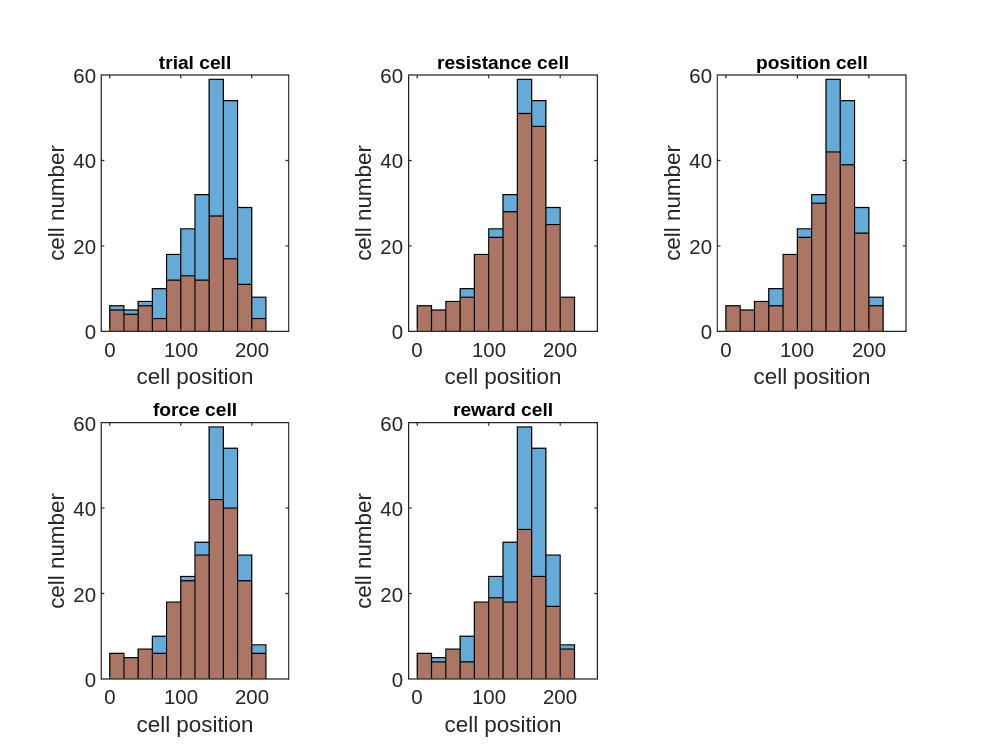

edges =      0    20    40    60    80   100   120   140   160   180   200   220   240


edges =      0    20    40    60    80   100   120   140   160   180   200   220   240


edges =      0    20    40    60    80   100   120   140   160   180   200   220   240


edges =      0    20    40    60    80   100   120   140   160   180   200   220   240


edges =      0    20    40    60    80   100   120   140   160   180   200   220   240


% plot the relation between position and representaion of each variables
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
figure
addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
titles = {'trial cell', 'resistance cell', 'position cell', 'force cell', 'reward cell'};
for i = 1:5
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.04, 'Padding', 0.04, 'Margin', 0.06);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
%     state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
%     imagesc(state_value_average_reshape,[0 1]);
%     colormap jet;
%     axis square;
%     axis off;
    edges = [0:20:240];
    h1 = histogram(centroidX,edges); %centroidY);
    hold on
    h2 = histogram(centroidX(cell_representations(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
    title(titles(i), 'FontSize',8);
    xlabel('cell position');
    ylabel('cell number');

end

% GLM_230210 = GLM;

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM'); % 'GLM_230210');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM');

% bin the state and action to calculate state value and action value
behavior_sequence_discretized = cell(1,length(data));

Unrecognized function or variable 'data'.

for i_trial = 1:length(data)
    % bin lever position (630-647 -> 6-1)
    position_temp = data{i_trial}(:,3);
    position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
%     position_discrete = 7 - min(max(idivide((position_temp - 623),4,'floor'),1),6);
%     position_discrete = zeros(length(position_temp));
%     for j_time = 1:length(position_temp)
%         if position_temp(j_time) <= 
    % bin applied force (0-0.7 -> 0-7)
    force_temp = data{i_trial}(:,4);
    force_discrete = min(max(floor(force_temp/0.1),0),7);
%     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
    behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
end

% analyze first 50 of last 50 trials as before and after adaptation
behavior_adapt = cell(2,50);
behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
state_value = cell(2,12);
for k = 1:2
    for i_trial = 1:50
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(2,12);
for i = 1:12
    state_value_average(1,i) = mean(state_value{1,i});
    state_value_average(2,i) = mean(state_value{2,i});
end
% rewarded after how many steps or not

% plot state value
state_value_average_reshape = reshape(state_value_average(1,:),[6,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')

% analyze by binned 20 trials
num_bins = 5; % 6 % number of bins
behavior_adapt = cell(num_bins,20);
for i = 1:num_bins
%     if i == 6
%         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
%     else
        behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
%     end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
state_value = cell(num_bins,12);
for k = 1:num_bins
    for i_trial = 1:20
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(num_bins,12);
for k = 1:num_bins
    for i = 1:12
        state_value_average(k,i) = mean(state_value{k,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

% plot state value
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');

end

% analyze by linearly increase the contribution of past trials
effective_trials = 50; % maximam trial which affect current state or action value
% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
trial_num = length(data);
state_value = cell(trial_num,12);
for i_trial = 1:trial_num
     % resistance for each trial
    if behavior_sequence_discretized{i_trial}(1,2) == 8
        resistance_trial = 1;
    else 
        resistance_trial = 2;
    end
    % rewarded step (end of trial) or not (0)
    if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
        rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
    else 
        rewarded_trial = 0;
    end
    % calculate state_value of each step
    for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
        state_temp = (resistance_trial-1)*6+behavior_sequence_discretized{i_trial}(j_step,7);
        if rewarded_trial >= 1
            state_value_temp = gamma.^(rewarded_trial-j_step);
        else
            state_value_temp = 0;
        end
        state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
    end   
end

state_value_average = zeros(trial_num,12);
for i_trial = 1:trial_num
    for i = 1:12
        state_value_average(i_trial,i) = mean(state_value{i_trial,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

% plot state value at trial50 
clf('reset')
state_value_weighted_average = zeros(1,12);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:12
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(50-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')

% plot state value at trial100 
% clf('reset')
state_value_weighted_average = zeros(1,12);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:12
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(100-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')

gamma = 0.9 % discount factor
x = 1:100;
y = gamma.^x;
plot(y)

steps = 0;
for i_trial = 1:length(data)
    steps = steps + length(data{i_trial});
end
steps = steps/length(data)

clf('reset')
max_forces = zeros(1,length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
histogram(max_forces, 'BinLimits',[0 1])